# Modelos cinemáticos de un robot serial 4R en el espacio

## Resumen

Este archivo incluye el planteamiento del modelo cinemático directo de la postura, el modelo cinemático directo de las velocidades, y el modelo cinemático inverso de la postura, junto con su solución.

## Bloque de funciones

Función general para una transformación homogénea entre dos sistemas de referencia, considerando traslaciones y rotaciones en 3D.

% Transformación homogenea
syms T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j)
T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j) = [cos(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j)-sin(alpha_i_j)*cos(gamma_i_j) sin(alpha_i_j)*sin(gamma_i_j)+cos(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j) x_i_j; sin(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*cos(gamma_i_j)+sin(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j) sin(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j)-cos(alpha_i_j)*sin(gamma_i_j) y_i_j; -sin(beta_i_j) cos(beta_i_j)*sin(gamma_i_j) cos(beta_i_j)*cos(gamma_i_j) z_i_j; 0 0 0 1]

$$T\_i\_j(x\_i\_j, y\_i\_j, z\_i\_j, gamma\_i\_j, beta\_i\_j, alpha\_i\_j) = \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)-\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & x_{i,j}\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & y_{i,j}\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Sistemas de referencia

El robot serial 4R tiene cinco eslabones en serie conectados por 4 juntas rotacionales.  El modelo desarrollado es una simplificación del Scorbot, omitiendo la orientación del efector final dada por el "roll" de la muñeca, tal como se muestra en la siguiente figura.

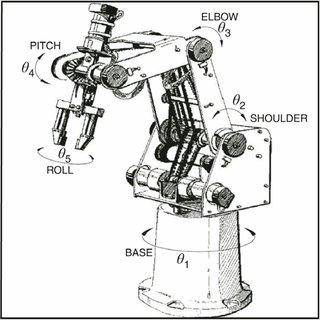

Para modelar el robot, se definen las relaciones de posición y orientación entre eslabones mediante sistemas de referencia. La cadena cinemática del robot se construye a partir de transformaciones homogenes, las cuales describen las traslaciones y rotaciones que relacionan los sistemas. La siguiente figura muestra los sistemas de referencia definidos.

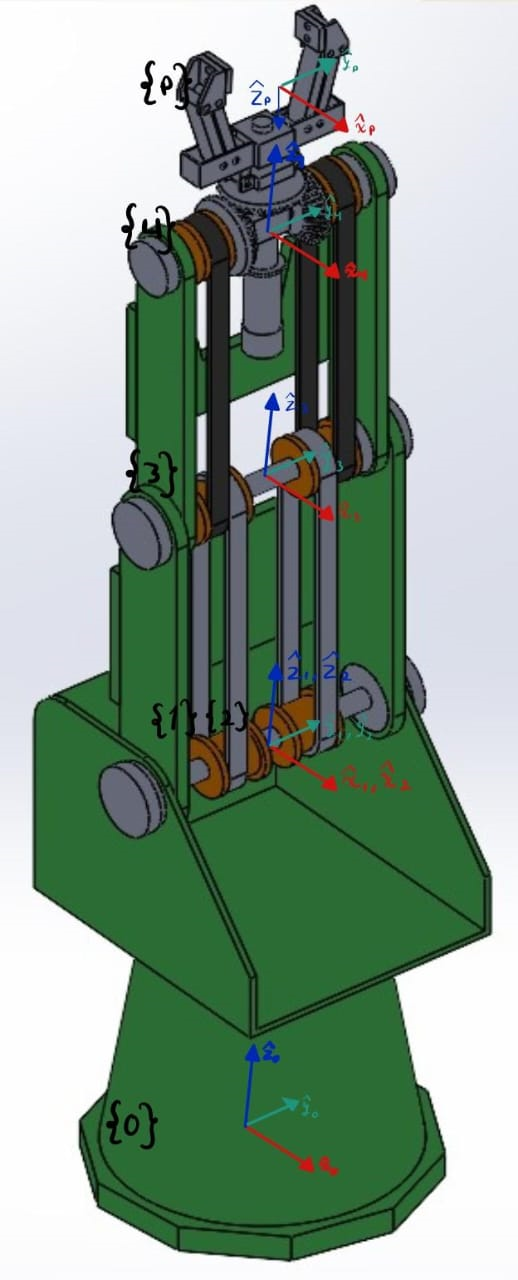

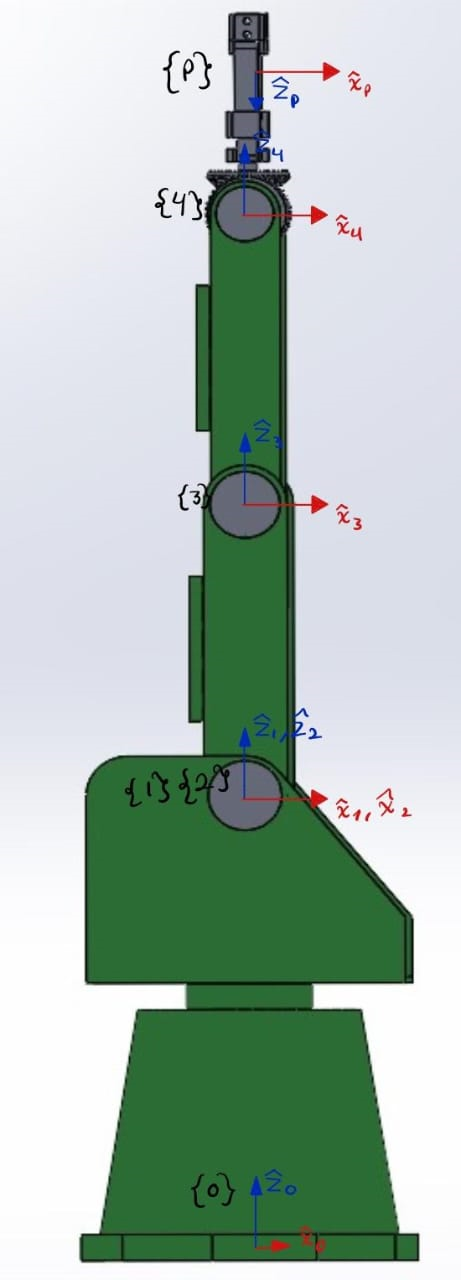

## Modelo cinemático directo de la postura

El modelo cinemático directo de la postura se determina mediante la transformación homogénea que relaciona el sistema inercial {0} con el sistema {p} asociado al efector final. Para ello, se establecen las transformaciones homogéneas que describen la relación entre los sistemas intermedios.

#### Sistema {1} visto desde el sistema {0}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_0$, cuya magnitud${}^0z_1$representa la altura desde la base hasta la junta del hombro, y una rotación alrededor del eje ${\hat{z} }_1$ con un ángulo${}^0{\theta }_1$que describe el movimiento de la cintura del robot.

syms T_0_1 z_0_1 theta_0_1 
T_0_1 = T_i_j(0, 0, z_0_1, 0, 0, theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {2} visto desde el sistema {1}

La transformación no incluye traslaciones, ya que los sistemas comparten el mismo punto de origen; sin embargo, incluye una rotación alrededor del eje ${\hat{y} }_2$ con un ángulo${}^1{\theta }_2$que describe el movimiento del hombro del robot.

syms T_1_2 x_1_2 z_1_2 theta_1_2
T_1_2 = T_i_j(0, 0, 0, 0, theta_1_2, 0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {3} visto desde el sistema {2}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_2$, cuya magnitud${}^2z_3$representa la longitud del brazo del robot, y una rotación alrededor del eje ${\hat{y} }_3$ con un ángulo${}^2{\theta }_3$que describe el movimiento del codo del robot.

syms T_2_3 z_2_3 theta_2_3
T_2_3 = T_i_j(0, 0, z_2_3, 0, theta_2_3, 0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {4} visto desde el sistema {3}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_3$, cuya magnitud${}^3z_4$representa la longitud del antebrazo del robot, y una rotación alrededor del eje ${\hat{y} }_4$ con un ángulo${}^3{\theta }_4$que describe el movimiento de la muñeca del robot.

syms T_3_4 z_3_4 theta_3_4
T_3_4 = T_i_j(0, 0, z_3_4, 0, theta_3_4, 0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {p} visto desde el sistema {4}

La transformación solo incluye una traslación a lo largo del eje ${\hat{z} }_4$, cuya magnitud${}^4z_p$representa la distancia desde la muñeca hasta el punto en el gripper donde el robot puede manipular objetos.

syms T_4_p z_4_p
T_4_p = T_i_j(0, 0, z_4_p, 0, 0, 0)

$$T\_4\_p = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{4,p}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {p} visto desde el sistema {0}

La transformación homogenea que relaciona el sistema inercial con el sistema del efector final se determina mediante la composición de las transformaciones homogeneas intermedias.


$${}^0T_p={}^0T_1{}^1T_2{}^2T_3{}^3T_4{}^4T_p$$


syms T_0_P
T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_p)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{3}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sigma_{1}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{3} & 0 & \sigma_{1} & z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,p}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,p}\,\sigma_{3}+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

#### Vector de postura del efector final

El vector de postura se define a partir de los vectores de posición y orientación del efector final.


$${}^0{\xi }_p={}^0{\xi }_p\left(q\right)$$


syms xi_0_P
xi_0_P = [T_0_P(1,4); T_0_P(2,4); T_0_P(3,4); atan2(T_0_P(3,2), T_0_P(3,3)); atan2(-T_0_P(3,1), sqrt(T_0_P(3,2)^2 + T_0_P(3,3)^2)); atan2(T_0_P(2,1), T_0_P(1,1))]

$$xi\_0\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,p}\,\sigma_{1}\\ \frac{\pi \,\mathrm{sign}\left(\sigma_{1}\right)\,\left(\mathrm{sign}\left(\sigma_{1}\right)-1\right)}{2}\\ \text{atan2}\left(\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right),\sqrt{{\sigma_{1}}^{2}}\right)\\ \text{atan2}\left(\sigma_{1}\,\sin\left(\theta_{0,1}\right),\sigma_{1}\,\cos\left(\theta_{0,1}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,p}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

## Modelo cinemático directo de las velocidades

El modelo cinemático directo de las velocidades se obtiene mediante la derivada total del modelo cinemático directo de la postura.


$${}^0{\dot{\xi} }_p=J_{\theta } \left(q\right)\dot{q}$$


#### Matriz Jacobiana

syms J_theta
J_theta = jacobian(xi_0_P, [theta_0_1, theta_1_2, theta_2_3, theta_3_4])

#### Vector de velocidades de las juntas

syms theta_dot theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4
theta_dot = [theta_dot_0_1; theta_dot_1_2; theta_dot_2_3; theta_dot_3_4]

$$theta\_dot = \left(\begin{array}{c} {\dot{\theta }}_{0,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{3,4} \end{array}\right)$$

#### Vector de velocidades del efector final

syms xi_dot_0_p
xi_dot_0_P = J_theta*theta_dot

## Modelo cinemático inverso de la postura

Nuevamente, una descripción del modelo y su ecuación.

#### Esta en sus manos jóven jajaja